networks = metropolis_hasting();
trained_network = networks{1,1};


probs = bayesian_classify([0.7;0.3], networks)

probs =     0.2800    0.7200


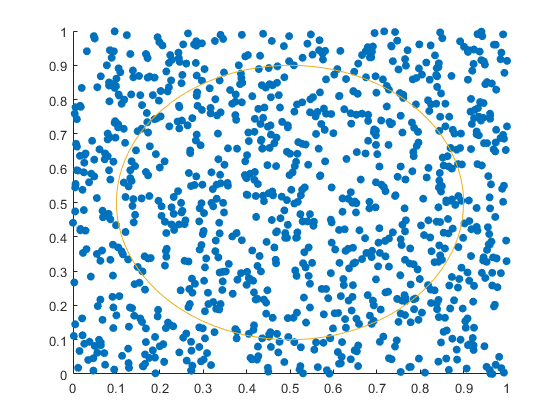

[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,200,"Cirkel");

x1_t = [data_XA data_XB];
x2_t = [data_YA data_YB];
N = length(x1_t);

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:N
    x = [x1_t(c); x2_t(c)];
    probs = bayesian_classify(x,networks);
    if probs(1) >= probs(2)
        XA = [XA, x1_t(c)];
        YA = [YA, x2_t(c)];
    else
        XB = [XB, x1_t(c)];
        YB = [YB, x2_t(c)];
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;

figure
hold on
axis([0 1 0 1])
%scatter(X,Y,[],'filled')
scatter(XA,YA,'filled')
scatter(XB,YB,'filled')
plot(xunit, yunit);

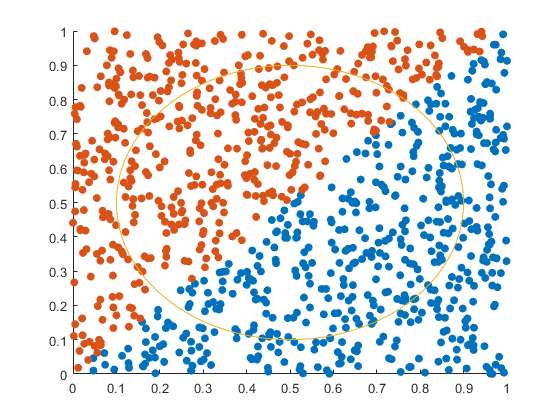

[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,200,"Cirkel");

x1_t = [data_XA data_XB];
x2_t = [data_YA data_YB];
N = length(x1_t);

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:N
    x = [x1_t(c); x2_t(c)];
    probs = classify(x,networks(1,1));
    if probs(1) >= probs(2)
        XA = [XA, x1_t(c)];
        YA = [YA, x2_t(c)];
    else
        XB = [XB, x1_t(c)];
        YB = [YB, x2_t(c)];
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;

figure
hold on
axis([0 1 0 1])
%scatter(X,Y,[],'filled')
scatter(XA,YA,'filled')
scatter(XB,YB,'filled')
plot(xunit, yunit);


[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,200,"Cirkel");

x1_t = [data_XA data_XB];
x2_t = [data_YA data_YB];
N = length(x1_t);

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:N
    x = [x1_t(c); x2_t(c)];
    probs = classify(x,networks(1,2));
    if probs(1) >= probs(2)
        XA = [XA, x1_t(c)];
        YA = [YA, x2_t(c)];
    else
        XB = [XB, x1_t(c)];
        YB = [YB, x2_t(c)];
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;

figure
hold on
axis([0 1 0 1])
%scatter(X,Y,[],'filled')
scatter(XA,YA,'filled')
scatter(XB,YB,'filled')
plot(xunit, yunit);


[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,200,"Cirkel");

x1_t = [data_XA data_XB];
x2_t = [data_YA data_YB];
N = length(x1_t);

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:N
    x = [x1_t(c); x2_t(c)];
    probs = classify(x,networks(1,3));
    if probs(1) >= probs(2)
        XA = [XA, x1_t(c)];
        YA = [YA, x2_t(c)];
    else
        XB = [XB, x1_t(c)];
        YB = [YB, x2_t(c)];
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;

figure
hold on
axis([0 1 0 1])
%scatter(X,Y,[],'filled')
scatter(XA,YA,'filled')
scatter(XB,YB,'filled')
plot(xunit, yunit);